We want to model the system using Euler-Lagrange modelling. We have two degrees of freedom $\theta_1$ and $\theta_2$.

clc; clear; close all;

%syms t
syms theta_1 theta_2 dtheta_1 dtheta_2 ddtheta_1 ddtheta_2

q = [theta_1; theta_2];
dq = [dtheta_1; dtheta_2];

We will first create kinetic and potential energy for the pendulum (system 2) and for the motor-stick (system 1)

syms m_1 m_2 l_1 l_2 J_1 J_2 
syms g

## System 1

% The motor stick does not have any potential energy assigned to it.
% It _is_ affected by gravity, but since gravity does not influence its
% movement path (that being in the x-/y-plane), it is not accounted for
E_pot1 = 0;

% Since it is a rotating system, it only has a  rotary kinetic energy, and
% no translatoric kinetic energy
E_kin1 = 1/2 * J_1 * dtheta_1^2;


## System 2

% The pendulum is affected by gravity, and thus the potential energy
% reflects that. The reference point (point-zero) is set at the swing-axis,
% therefore the potential energy is dependent on the pendulums distance
% from said reference point.
% 0 degrees is also defined now. It is defined to be when the pendulum
% hangs downwards, thus making 180 degrees the point where it stands
% straight up.
% Then the potential energy is
E_pot2 = -m_2*l_2*g*cos(theta_2);

% The pendulum has both a rotary and a translatoric kinetic energy. The
% rotary kinetic energy is only dependent on the pendulum itself, but the
% translatoric kinetic energy is dependent on both the motor-stick and the
% pendulum's rotary speed (depending on the axis)
% For the up-down axis, z, the pendulums translatoric kinetic energy will
% be
E_kin2_z = 1/2 * m_2 * (l_2*dtheta_2*sin(theta_2))^2;

% The x-/y-axis translatoric energy is dependent on the motor-sticks speed
% at the pendulum's swing-axis. This is calculated as
v_1 = l_1 * dtheta_1;

% And thus the translatoric kinetic energy in the x-/y-axis for the
% pendulum is
E_kin2_xy = 1/2 * m_2 * (v_1 + l_2 * dtheta_2 * cos(theta_2))^2;

% And the rotary kinetic energy for the pendulum follows the same structure
% as that for the motor-stick. Thus being
E_kin2_rot = 1/2 * J_2 * dtheta_2^2;

% Finally, the kinetic energy for the pendulum is
E_kin2 = E_kin2_rot + E_kin2_xy + E_kin2_z;


## Whole system

% We can now combine the energies of system 1 and system 2 to form the
% system as a whole
E_pot = E_pot1 + E_pot2;

E_kin = E_kin1 + E_kin2;


## Lagrangian

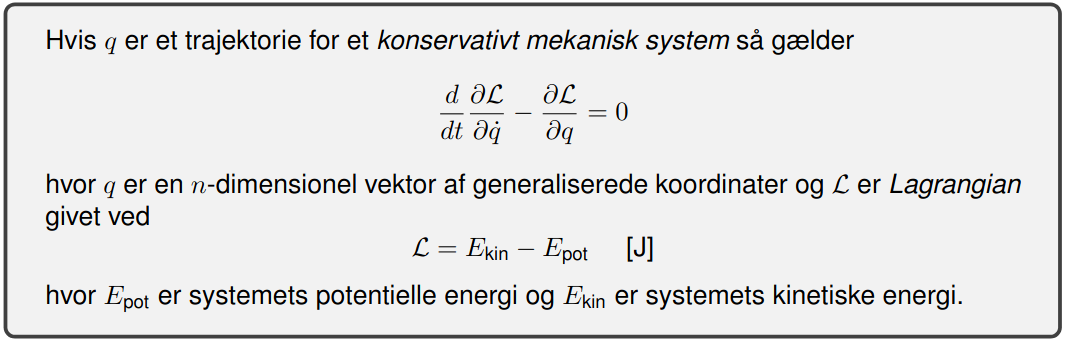

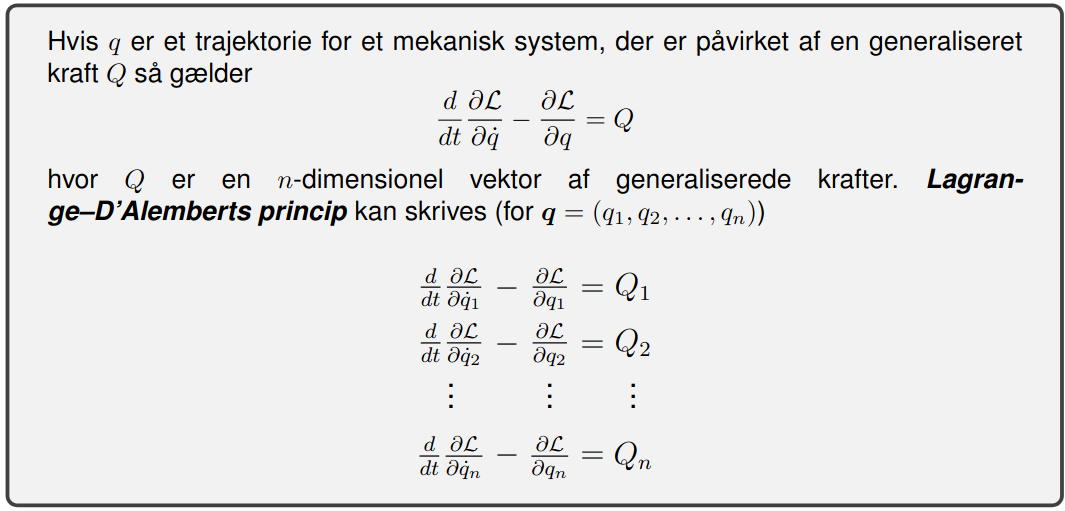

We will now do the Euler-Lagrange modelling following the above method

% Lagrangian
Lagrange = E_kin - E_pot;

qL1 = simplify(diff(Lagrange, q(1)))

$$qL1 = 0$$

qL2 = simplify(diff(Lagrange, q(2)))

$$qL2 = -l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,\left(g+{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,l_{1}\right)$$

dqL1 = simplify(diff(Lagrange, dq(1)))

$$dqL1 = J_{1}\,{\mathrm{dtheta}}_{1}+l_{1}\,m_{2}\,\left({\mathrm{dtheta}}_{1}\,l_{1}+{\mathrm{dtheta}}_{2}\,l_{2}\,\cos\left(\theta_{2}\right)\right)$$

dqL2 = simplify(diff(Lagrange, dq(2)))

$$dqL2 = {\mathrm{dtheta}}_{2}\,m_{2}\,{l_{2}}^{2}+{\mathrm{dtheta}}_{1}\,l_{1}\,m_{2}\,\cos\left(\theta_{2}\right)\,l_{2}+J_{2}\,{\mathrm{dtheta}}_{2}$$

qL = [qL1; qL2];
% We will now need to differentiate dqL1 and dqL2 with t. This is done
% manually (as I have not set it up properly to do it by MATLAB...)


$$\frac{d}{\textrm{dt}}*\textrm{dqL1}=J_1 \ddot{\;\theta_1 } +l_1 m_2 \left(\ddot{\;\theta_1 } l_1 -\ddot{\;\theta_2 } l_2 \;\dot{\;\theta_2 \;} \sin \left(\theta_2 \right)\right)$$



$$\frac{d}{\textrm{dt}}*\textrm{dqL2}=\ddot{\;\theta_2 } m_2 l_2^2 -\ddot{\theta_1 } l_1 m_2 \dot{\;\theta_2 } \sin \left(\theta_2 \right)l_2 +J_2 \ddot{\;\theta_2 }$$


% Now we just write it to matlab code, so that we can use it
dqL1_t = J_1 * ddtheta_1 + l_1 * m_2 * (ddtheta_1 * l_1 - ddtheta_2 * l_2 * dtheta_2 * sin(theta_2));
dqL2_t = J_2 * ddtheta_2 + ddtheta_2 * m_2 * l_2^2 - ddtheta_1 * l_1 * m_2 * dtheta_2 * sin(theta_2);

dqL_t = [dqL1_t; dqL2_t];

% Non-conservative forces
% Both the pendulum and the motor-stick will be affected by _some_
% friction.
% The motor stick will also be affected by the motor-torque, that is
% inputted to the system.
syms b_1 b_2 tau_m
Q = [-b_1 * dtheta_1 + tau_m;
     -b_2 * dtheta_2];

% Finally, we can calculate the system's movement-equations using the
% method from the pictures above
sys = Q == dqL_t - qL

$$sys = \left(\begin{array}{c} \tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}=J_{1}\,{\mathrm{ddtheta}}_{1}+l_{1}\,m_{2}\,\left({\mathrm{ddtheta}}_{1}\,l_{1}-{\mathrm{ddtheta}}_{2}\,{\mathrm{dtheta}}_{2}\,l_{2}\,\sin\left(\theta_{2}\right)\right)\\ -b_{2}\,{\mathrm{dtheta}}_{2}={\mathrm{ddtheta}}_{2}\,m_{2}\,{l_{2}}^{2}+m_{2}\,\sin\left(\theta_{2}\right)\,\left(g+{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,l_{1}\right)\,l_{2}+J_{2}\,{\mathrm{ddtheta}}_{2}-{\mathrm{ddtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,l_{1}\,m_{2}\,\sin\left(\theta_{2}\right) \end{array}\right)$$

sys1 = isolate(simplify(sys(1)), J_1*ddtheta_1) % Motor stick

$$sys1 = J_{1}\,{\mathrm{ddtheta}}_{1}=\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}-l_{1}\,m_{2}\,\left({\mathrm{ddtheta}}_{1}\,l_{1}-{\mathrm{ddtheta}}_{2}\,{\mathrm{dtheta}}_{2}\,l_{2}\,\sin\left(\theta_{2}\right)\right)$$

sys2 = isolate(simplify(sys(2)), J_2*ddtheta_2) % Pendulum

$$sys2 = J_{2}\,{\mathrm{ddtheta}}_{2}=-{\mathrm{ddtheta}}_{2}\,m_{2}\,{l_{2}}^{2}-m_{2}\,\sin\left(\theta_{2}\right)\,\left(g+{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,l_{1}\right)\,l_{2}-b_{2}\,{\mathrm{dtheta}}_{2}+{\mathrm{ddtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,l_{1}\,m_{2}\,\sin\left(\theta_{2}\right)$$

% Noget gået galt, da ddtheta både 1 og 2 indgår på begge sidder
% af lighedstegnene.

## Time domain models

We now try to write up state space models for the system, that can later be converted to transfer functions.

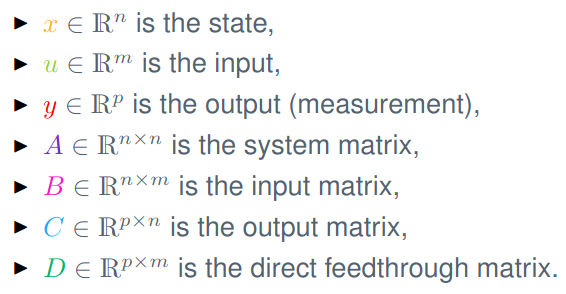

We will want to use the torque $\tau_m$ as an input and get the angular velocity of the pendulum $\dot{\theta_2 }$ as an output. We want this to be zero. We also want the angle $\theta_2$ to be 180 degrees (but this is for another time...)

% State space vectors
x_1 = [theta_1; dtheta_1];
x_2 = [theta_2; dtheta_2];
x = [x_1; x_2];

% System vectors
dx_1 = [dtheta_1; ddtheta_1];
dx_2 = [dtheta_2; ddtheta_2];
dx = [dx_1; dx_2];

% A matrix (found by isolating ddtheta in the system formulars)
sys1_A = isolate(sys1, ddtheta_1)

$$sys1\_A = {\mathrm{ddtheta}}_{1}=\frac{\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}+{\mathrm{ddtheta}}_{2}\,{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{m_{2}\,{l_{1}}^{2}+J_{1}}$$

sys2_A = isolate(sys2, ddtheta_2)

$$sys2\_A = {\mathrm{ddtheta}}_{2}=-\frac{b_{2}\,{\mathrm{dtheta}}_{2}+l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,\left(g+{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,l_{1}\right)-{\mathrm{ddtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,l_{1}\,m_{2}\,\sin\left(\theta_{2}\right)}{m_{2}\,{l_{2}}^{2}+J_{2}}$$

A = [0 1 0 0;
     0 -b_1/(m_2*l_1^2+J_1) %sin(theta_2)???? %hvordan pokker skal jeg opdele dtheta_2 udtrykket?]

Error using catMany>checkDimensions (line 53)
Dimensions of objects being concatenated must match.

Error in catMany (line 12)
[resz, ranges] = checkDimensions(sz, dim);

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('sym/vertcat', '/usr/local/MATLAB/R2024b/toolbox/symbolic/symbolic/@sym/vertcat.m', 20)" style="font-weight:bold">sym/vertcat<